clear all
clc
close all
t = 0:15;
f = [0 0 0 1 0 0 1 0 0 0 0 1 1 1 0 1 ];
f_bar = [0 1 0 0 0 1 1 1 0 1 0 0 1 0 0 0 ];


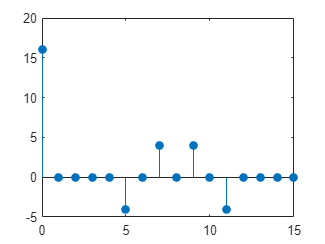

%periodic sequence
%set autocorrelations for f

reg_plus_f_auto = zeros(1,16);
reg_shift = f;


for k = 1:16
    for i = 1:16
        if(reg_shift(i) == f(i));
            reg_plus_f_auto(1,k) = reg_plus_f_auto(1,k) + 1;
        else (reg_shift(i) ~= f(i));
            reg_plus_f_auto(1,k) = reg_plus_f_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_f_auto,"filled");

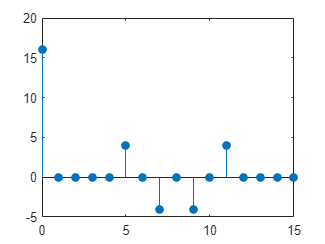

%set autocorrelations for f_bar
reg_plus_f_bar_auto = zeros(1,16);
reg_shift = f_bar;


for k = 1:16
    for i = 1:16
        if(reg_shift(i) == f_bar(i));
            reg_plus_f_bar_auto(1,k) = reg_plus_f_bar_auto(1,k) + 1;
        else (reg_shift(i) ~= f_bar(i));
            reg_plus_f_bar_auto(1,k) = reg_plus_f_bar_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_f_bar_auto,"filled");

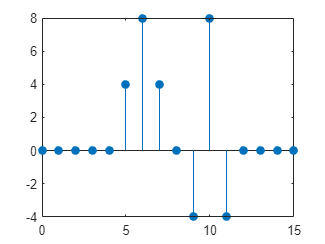

%set crosscorrletion for f and f_bar
reg_plus_f_cross = zeros(1,16);

for k = 1:16
    for i = 1:16
        if(f(i) == f_bar(i));
            reg_plus_f_cross(1,k) = reg_plus_f_cross(1,k) + 1;
        else (f(i) ~= f_bar(i));
            reg_plus_f_cross(1,k) = reg_plus_f_cross(1,k) - 1;
        end    
    end
    f_bar = circshift(f_bar,1);
end

stem(t,reg_plus_f_cross,"filled");

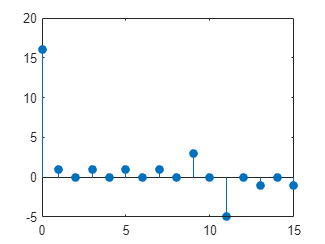

%aperiodic sequence
%set autocorrelations for f
reg_plus_ap_f_auto = zeros(1,16);
reg_shift = f;

for k = 1:16
    for i = k:16
        if(f(i) == reg_shift(i));
            reg_plus_ap_f_auto(1,k) = reg_plus_ap_f_auto(1,k) + 1;
        else (f(i) ~= reg_shift(i));
            reg_plus_ap_f_auto(1,k) = reg_plus_ap_f_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_ap_f_auto,"filled");

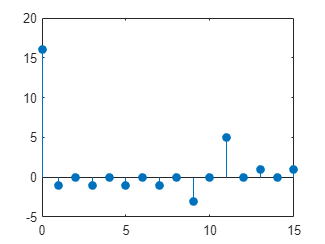

%set autocorrelations for f_bar
reg_plus_ap_f_bar_auto = zeros(1,16);
reg_shift = f_bar;


for k = 1:16
    for i = k:16
        if(reg_shift(i) == f_bar(i));
            reg_plus_ap_f_bar_auto(1,k) = reg_plus_ap_f_bar_auto(1,k) + 1;
        else (reg_shift(i) ~= f_bar(i));
            reg_plus_ap_f_bar_auto(1,k) = reg_plus_ap_f_bar_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_ap_f_bar_auto,"filled");

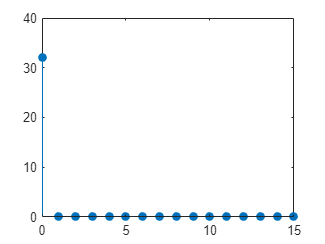

f_plus = reg_plus_ap_f_bar_auto + reg_plus_ap_f_auto;
stem(t,f_plus,"filled");

%To calculate the Pc(t)
sample = 210;
for T = 1:sample;
    t = T / sample;
    for u = 1:15
        %summation to caclulate
        Pc(1,1) = 16;
        Pc(1,u+1) = 2*reg_plus_ap_f_auto(1,u+1)*cos(2*pi*t*u);
        
        %integral to caclulate 
        Pc_function = @(t) 16 + 2*reg_plus_ap_f_auto(1,u+1)*cos(2*pi*t*u);
        Pav = (1/t)*integral(Pc_function,0,t);

    end
    Pc_sum = sum(Pc)
    PAPR(1,T) = Pc_sum/Pav;
end

Pc_sum = 16.5930

Pc_sum = 18.2708

Pc_sum = 20.7462

Pc_sum = 23.5914

Pc_sum = 26.3058

Pc_sum = 28.3949

Pc_sum = 29.4477

Pc_sum = 29.2005

Pc_sum = 27.5774

Pc_sum = 24.7012

Pc_sum = 20.8747

Pc_sum = 16.5347

Pc_sum = 12.1885

Pc_sum = 8.3418

Pc_sum = 5.4300

Pc_sum = 3.7629

Pc_sum = 3.4897

Pc_sum = 4.5891

Pc_sum = 6.8825

Pc_sum = 10.0675

Pc_sum = 13.7639

Pc_sum = 17.5657

Pc_sum = 21.0887

Pc_sum = 24.0097

Pc_sum = 26.0920

Pc_sum = 27.1971

Pc_sum = 27.2827

Pc_sum = 26.3920

Pc_sum = 24.6368

Pc_sum = 22.1806

Pc_sum = 19.2227

Pc_sum = 15.9860

Pc_sum = 12.7077

Pc_sum = 9.6318

Pc_sum = 7.0000

Pc_sum = 5.0398

Pc_sum = 3.9483

Pc_sum = 3.8724

Pc_sum = 4.8865

Pc_sum = 6.9731

Pc_sum = 10.0092

Pc_sum = 13.7639

Pc_sum = 17.9097

Pc_sum = 22.0483

Pc_sum = 25.7506

Pc_sum = 28.6055

Pc_sum = 30.2712

Pc_sum = 30.5226

Pc_sum = 29.2860

Pc_sum = 26.6560

Pc_sum = 22.8903

Pc_sum = 18.3827

Pc_sum = 13.6173

Pc_sum = 9.1097

Pc_sum = 5.3440

Pc_sum = 2.7140

Pc_sum = 1.4774

Pc_sum = 1.7288

Pc_sum = 3.3945

Pc_sum = 6.2494

Pc_sum = 9.9517

Pc_sum = 14.0903

Pc_sum = 18.2361

Pc_sum = 21.9908

Pc_sum = 25.0269

Pc_sum = 27.1135

Pc_sum = 28.1276

Pc_sum = 28.0517

Pc_sum = 26.9602

Pc_sum = 25.0000

Pc_sum = 22.3682

Pc_sum = 19.2923

Pc_sum = 16.0140

Pc_sum = 12.7773

Pc_sum = 9.8194

Pc_sum = 7.3632

Pc_sum = 5.6080

Pc_sum = 4.7173

Pc_sum = 4.8029

Pc_sum = 5.9080

Pc_sum = 7.9903

Pc_sum = 10.9113

Pc_sum = 14.4343

Pc_sum = 18.2361

Pc_sum = 21.9325

Pc_sum = 25.1175

Pc_sum = 27.4109

Pc_sum = 28.5103

Pc_sum = 28.2371

Pc_sum = 26.5700

Pc_sum = 23.6582

Pc_sum = 19.8115

Pc_sum = 15.4653

Pc_sum = 11.1253

Pc_sum = 7.2988

Pc_sum = 4.4226

Pc_sum = 2.7995

Pc_sum = 2.5523

Pc_sum = 3.6051

Pc_sum = 5.6942

Pc_sum = 8.4086

Pc_sum = 11.2538

Pc_sum = 13.7292

Pc_sum = 15.4070

Pc_sum = 16

Pc_sum = 15.4070

Pc_sum = 13.7292

Pc_sum = 11.2538

Pc_sum = 8.4086

Pc_sum = 5.6942

Pc_sum = 3.6051

Pc_sum = 2.5523

Pc_sum = 2.7995

Pc_sum = 4.4226

Pc_sum = 7.2988

Pc_sum = 11.1253

Pc_sum = 15.4653

Pc_sum = 19.8115

Pc_sum = 23.6582

Pc_sum = 26.5700

Pc_sum = 28.2371

Pc_sum = 28.5103

Pc_sum = 27.4109

Pc_sum = 25.1175

Pc_sum = 21.9325

Pc_sum = 18.2361

Pc_sum = 14.4343

Pc_sum = 10.9113

Pc_sum = 7.9903

Pc_sum = 5.9080

Pc_sum = 4.8029

Pc_sum = 4.7173

Pc_sum = 5.6080

Pc_sum = 7.3632

Pc_sum = 9.8194

Pc_sum = 12.7773

Pc_sum = 16.0140

Pc_sum = 19.2923

Pc_sum = 22.3682

Pc_sum = 25.0000

Pc_sum = 26.9602

Pc_sum = 28.0517

Pc_sum = 28.1276

Pc_sum = 27.1135

Pc_sum = 25.0269

Pc_sum = 21.9908

Pc_sum = 18.2361

Pc_sum = 14.0903

Pc_sum = 9.9517

Pc_sum = 6.2494

Pc_sum = 3.3945

Pc_sum = 1.7288

Pc_sum = 1.4774

Pc_sum = 2.7140

Pc_sum = 5.3440

Pc_sum = 9.1097

Pc_sum = 13.6173

Pc_sum = 18.3827

Pc_sum = 22.8903

Pc_sum = 26.6560

Pc_sum = 29.2860

Pc_sum = 30.5226

Pc_sum = 30.2712

Pc_sum = 28.6055

Pc_sum = 25.7506

Pc_sum = 22.0483

Pc_sum = 17.9097

Pc_sum = 13.7639

Pc_sum = 10.0092

Pc_sum = 6.9731

Pc_sum = 4.8865

Pc_sum = 3.8724

Pc_sum = 3.9483

Pc_sum = 5.0398

Pc_sum = 7.0000

Pc_sum = 9.6318

Pc_sum = 12.7077

Pc_sum = 15.9860

Pc_sum = 19.2227

Pc_sum = 22.1806

Pc_sum = 24.6368

Pc_sum = 26.3920

Pc_sum = 27.2827

Pc_sum = 27.1971

Pc_sum = 26.0920

Pc_sum = 24.0097

Pc_sum = 21.0887

Pc_sum = 17.5657

Pc_sum = 13.7639

Pc_sum = 10.0675

Pc_sum = 6.8825

Pc_sum = 4.5891

Pc_sum = 3.4897

Pc_sum = 3.7629

Pc_sum = 5.4300

Pc_sum = 8.3418

Pc_sum = 12.1885

Pc_sum = 16.5347

Pc_sum = 20.8747

Pc_sum = 24.7012

Pc_sum = 27.5774

Pc_sum = 29.2005

Pc_sum = 29.4477

Pc_sum = 28.3949

Pc_sum = 26.3058

Pc_sum = 23.5914

Pc_sum = 20.7462

Pc_sum = 18.2708

Pc_sum = 16.5930

Pc_sum = 16

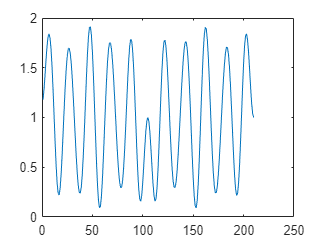

PAPR_MAX = max(PAPR);
plot(PAPR);